# Train DDPG Agent to Swing Up and Balance Cart-Pole System

This example shows how to train a deep deterministic policy gradient (DDPG) agent to swing up and balance a cart-pole system modeled in Simscape™ Multibody™.

For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). For an example showing how to train a DDPG agent in MATLAB®, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Cart-Pole Simscape Model

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pole stand upright without falling over using minimal control effort.

Open the model.

mdl = 'rlCartPoleSimscapeModel';
open_system(mdl)

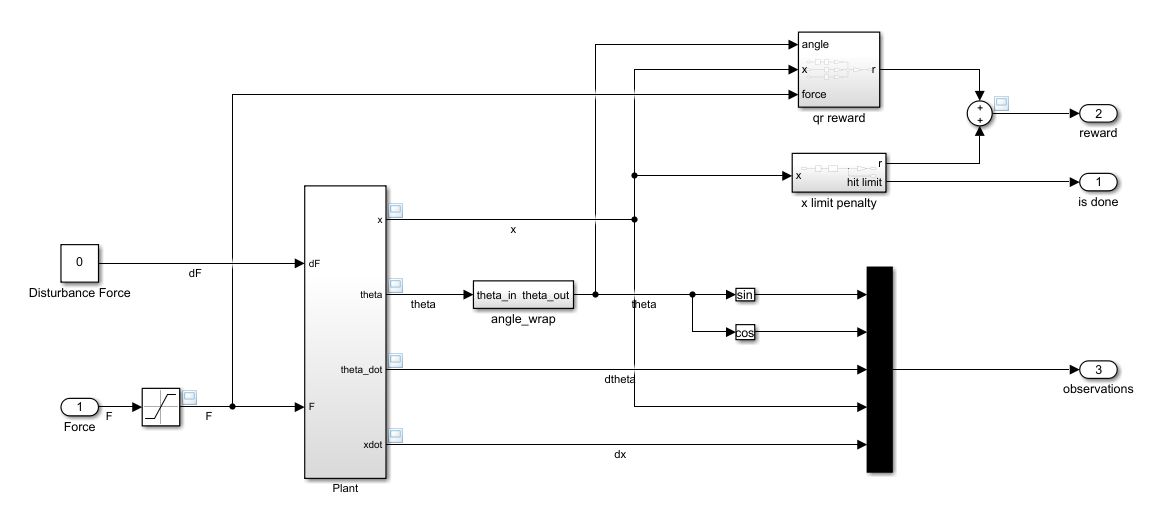

The cart-pole system is modeled using Simscape Multibody.

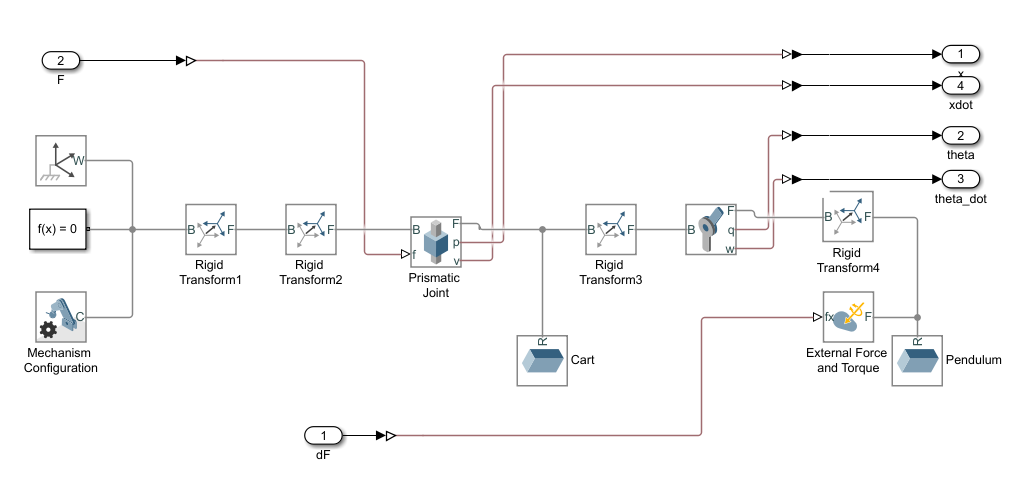

For this model:

- The upward balanced pole position is `0` radians, and the downward hanging position is `pi` radians.

- The force action signal from the agent to the environment is from –15 to 15 N.

- The observations from the environment are the position and velocity of the cart, and the sine, cosine, and derivative of the pole angle.

- The episode terminates if the cart moves more than 3.5 m from the original position.

- The reward $r_t$, provided at every timestep, is


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =\;-0\ldotp 1\left(5{\theta_{\mathit{\mathbf{t}}} }^2 \;+{x_{\mathit{\mathbf{t}}} }^2 \;+\;0\ldotp 05u_{t-1}^2 \right)-100B$$


Here:

- $\theta_t$ is the angle of displacement from the upright position of the pole.

- $x_t$ is the position displacement from the center position of the cart.

- $u_{t-1}$ is the control effort from the previous time step.

- $B$ is a flag (1 or 0) that indicates whether the cart is out of bounds.

For more information on this model, see [Load Predefined Simulink Environments](docid:rl_ug#mw_9372e520-2760-4363-a7ea-983478559539).

## Create Environment Interface

Create a predefined environment interface for the pole.

env = rlPredefinedEnv('CartPoleSimscapeModel-Continuous')

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlCartPoleSimscapeModel
      AgentBlock : rlCartPoleSimscapeModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The interface has a continuous action space where the agent can apply possible torque values from –15 to 15 N to the pole.

Obtain the observation and action information from the environment interface. 

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "observations"
    Description: [0×0 string]
      Dimension: [5 1]
       DataType: "double"


numObservations = obsInfo.Dimension(1)

numObservations = 5

actInfo = getActionInfo(env)

actInfo =   rlNumericSpec with properties:

     LowerLimit: -15
     UpperLimit: 15
           Name: "force"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


Specify the simulation time `Tf` and the agent sample time `Ts` in seconds

Ts = 0.02;
Tf = 25;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

A DDPG agent approximates the long-term reward, given observations and actions, using a critic value function representation. To create the critic, first create a deep neural network with two inputs (the state and action) and one output. The input size of action path is `[1 1 1]` since the agent can apply an action as one force value to the environment. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(200,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(200,'Name','CriticActionFC1','BiasLearnRateFactor',0)];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

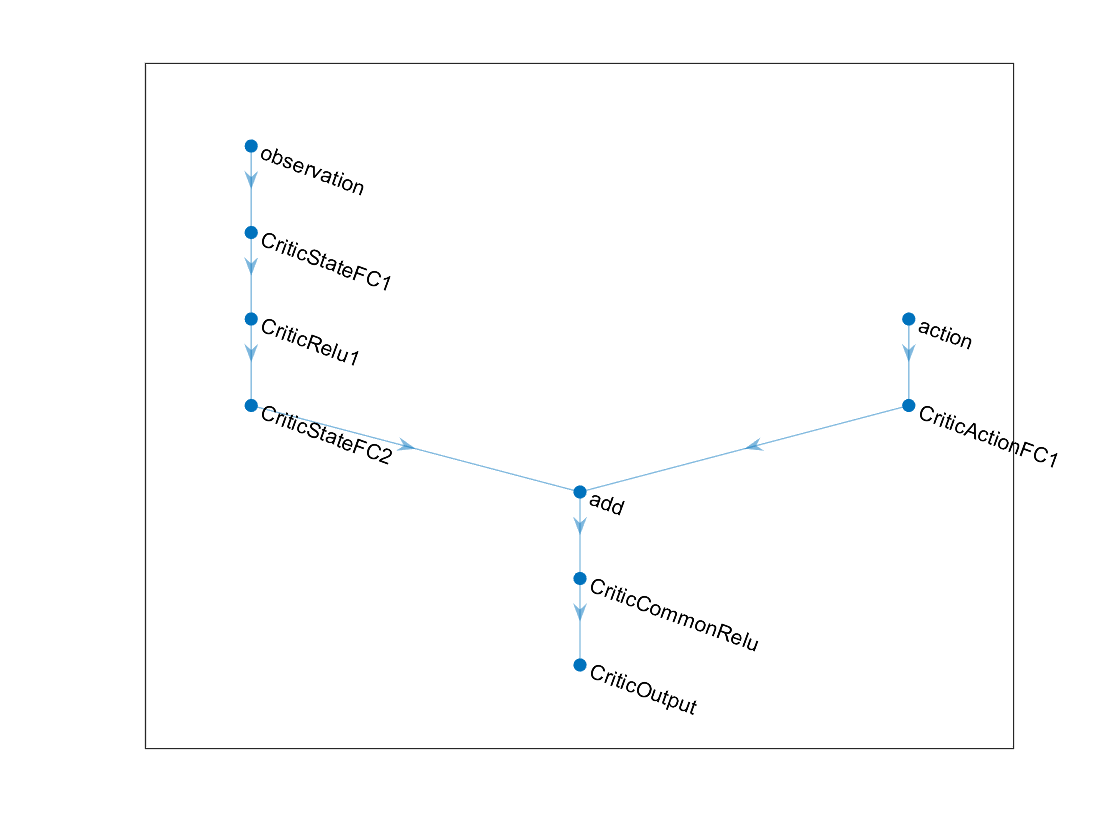

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you already obtained from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

A DDPG agent decides which action to take, given observations, using an actor representation. To create the actor, first create a deep neural network with one input (the observation) and one output (the action).

Construct the actor in a similar manner to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(200,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(1,'Name','ActorFC3')
    tanhLayer('Name','ActorTanh1')
    scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];

actorOptions = rlRepresentationOptions('LearnRate',5e-04,'GradientThreshold',1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'ActorScaling'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',128);
agentOptions.NoiseOptions.StandardDeviation = 0.4;
agentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-5;

Then, create the agent using the specified actor representation, critic representation and agent options. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run each training episode for at most 2000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than –400 over five consecutive episodes. At this point, the agent can quickly balance the pole in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than –400.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 2000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'ScoreAveragingWindowLength',5,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-400,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',-400);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions);
else
    % Load the pretrained agent for the example.
    load('SimscapeCartPoleDDPG.mat','agent')
end

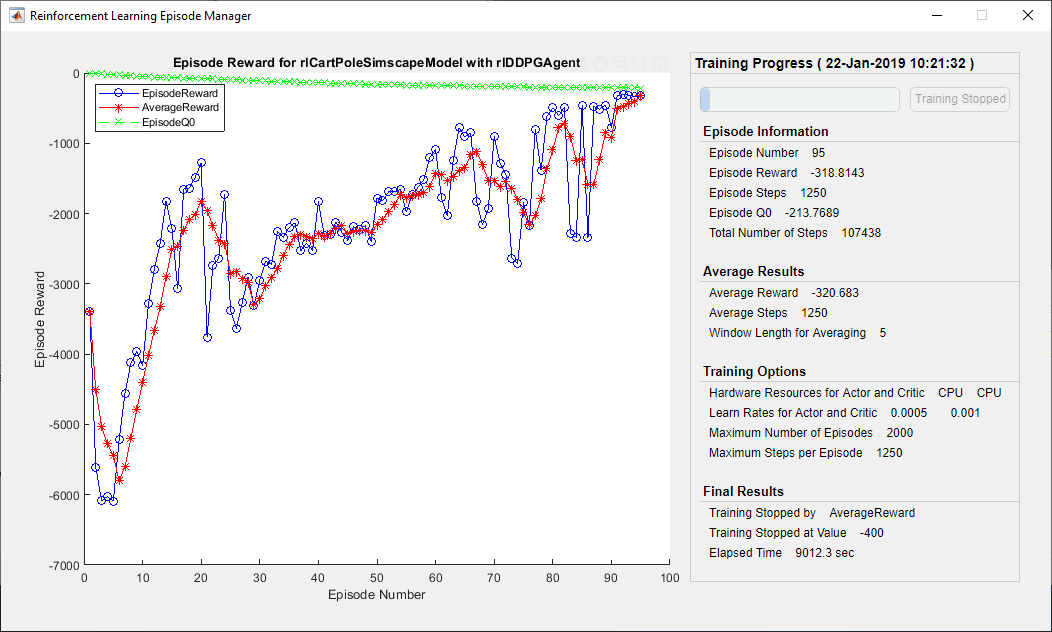

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

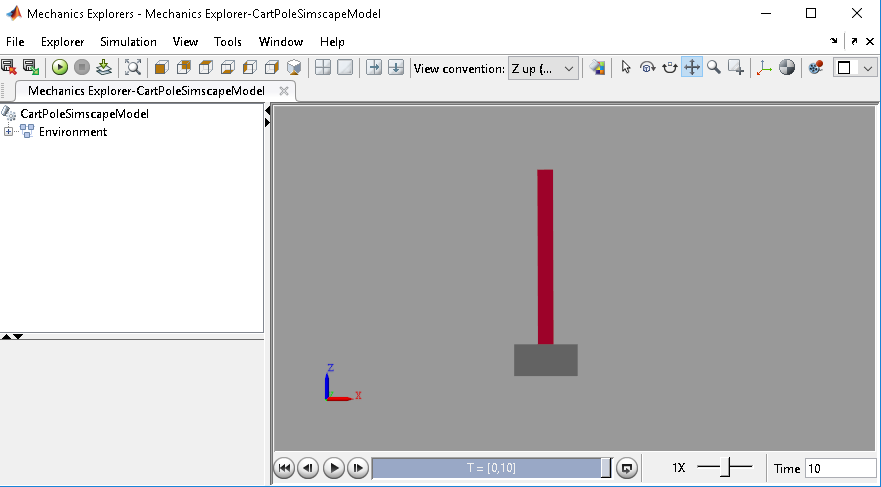

% bdclose(mdl)

*Copyright 2019 The MathWorks, Inc.*